## **Practical Problems 1 - Basic Commands**

1. In MATLAB, create vectors x = (1,2,3,4,5) and y = (1,2,3,4,5) using any two different methods. 

x = 1:5

x =      1     2     3     4     5


y = [1, 2, 3, 4, 5]

y =      1     2     3     4     5


2. Add the two vectors together and examine the output. 

out = x + y

out =      2     4     6     8    10


3. Sum the elements of the answer to question 2.

out3 = sum(out)

out3 = 30

4. Add the 3rd element of `x` to the last element of `y`, and assign the output to the variable `z`.

z = x(3) + y(end)

z = 8

5. Replace the 4th element of `x` with 7.

x(4) = 7

x =      1     2     3     7     5


6. Extend the vector `y` with the value 6 so that it has 6 elements.

while length(y)~= 6
    y(end+1) = 6
end

y =      1     2     3     4     5     6


7. Shorten the vector `y` by assigning the empty matrix to element 3.

y(3) = []

y =      1     2     4     5     6


8. Create three column vectors of length 3 named `c1`,` c2`, and `c3`. Create a 3x3 matrix called `A` using these column vectors.

c1 = [1; 2; 3]

c1 =      1
     2
     3


c2 = [4; 5; 6]

c2 =      4
     5
     6


c3 = [7; 8; 9]

c3 =      7
     8
     9


A = [c1, c2, c3]

A =      1     4     7
     2     5     8
     3     6     9


9. Calculate the determinant of the matrix `B`**.**

B = [1, 2, 3; 4, 5, 6; 7, 8, 9]

B =      1     2     3
     4     5     6
     7     8     9


det(B)

ans = 6.6613e-16

10. Calculate the eigenvalues of the matrix `B`

eig(B)

ans =    16.1168
   -1.1168
   -0.0000


11. Create a row vector,

      and a column vector,

    

a = [3, 6, 9]

a =      3     6     9


b = [3; 6; 9]

b =      3
     6
     9


12. Perform matrix and then element-wise multiplication on these two vectors. Can you explain the error in the second case if your Matlab version is before 2017, or can you explain what is happening in later versions of Matlab? 

mult = a * b

mult = 126

eleMult = a.*b

eleMult =      9    18    27
    18    36    54
    27    54    81


13. Transpose the vector `a` and create a 3x2 matrix called **myMat** using it with `b`.

myMat = [a',b]

myMat =      3     3
     6     6
     9     9


14. Add the second element on the first row to the first element of the second row.

myMat(1, 2) + myMat(2, 1)

ans = 9

15. Create a random 2x2 array of non-integer numbers and give it a name.

x15 = rand([2 2])

x15 =     0.3683    0.9382
    0.6556    0.6204


16. Round the array to the nearest integer.

x15 = round(x15)

x15 =      0     1
     1     1


17. Find the number of elements in the array.

numel(x15)

ans = 4

18. Find its maximum and minimum values.

max(x15)

ans =      1     1


min(x15)

ans =      0     1


19. Find the maximum value on the 2nd row using a single command.

max(x15(2))

ans = 1

20. Create a random vector of non-integers of length 8 and give it a name.

x20 = rand([1, 8], "double")

x20 =     0.2828    0.2052    0.4391    0.0273    0.8762    0.6101    0.2036    0.5199


21. Sort the vector into ascending order.

sort(x20, "ascend")

ans =     0.0273    0.2036    0.2052    0.2828    0.4391    0.5199    0.6101    0.8762


22. Round the 2nd, 4th, 6th and 8th elements **up** to the nearest integer, and the 1st, 3rd, 5th and 7th elements **down** to the nearest integer.

for n = 1:numel(x20)
    if mod(n,2) == 0
        x20(n) = ceil(x20(n))
    else
        x20(n) = floor(x20(n))
    end
end

x20 =          0    0.2052    0.4391    0.0273    0.8762    0.6101    0.2036    0.5199


x20 =          0    1.0000    0.4391    0.0273    0.8762    0.6101    0.2036    0.5199


x20 =          0    1.0000         0    0.0273    0.8762    0.6101    0.2036    0.5199


x20 =          0    1.0000         0    1.0000    0.8762    0.6101    0.2036    0.5199


x20 =          0    1.0000         0    1.0000         0    0.6101    0.2036    0.5199


x20 =          0    1.0000         0    1.0000         0    1.0000    0.2036    0.5199


x20 =          0    1.0000         0    1.0000         0    1.0000         0    0.5199


x20 =      0     1     0     1     0     1     0     1


23. Generate a random 9x9 matrix of integers called `C`.

c = randi(9, [9, 9])

c =      1     1     7     1     8     3     3     9     1
     8     7     9     5     7     3     9     5     7
     4     1     4     6     3     3     2     3     2
     5     9     7     2     7     9     8     6     4
     6     7     1     5     3     8     1     9     4
     7     9     6     6     3     4     3     9     8
     4     5     4     8     1     5     7     5     1
     1     3     7     3     4     6     6     4     8
     5     3     3     4     4     5     2     3     3


24. Add the 4th column of `C` to the 6th column.

c(1:end,4) + c(1:end,6)

ans =      4
     8
     9
    11
    13
    10
    13
     9
     9


25. Create a 3x3 matrix `D` from the top left minor of matrix `C`, and a matrix `E` from the bottom right minor of matrix `C`

d = c(1:3, 1:3)

d =      1     1     7
     8     7     9
     4     1     4


e = c(end-3:end, end-3:end)

e =      4     3     9     8
     5     7     5     1
     6     6     4     8
     5     2     3     3


26. Perform the element-wise multiplication `DE` and `ED`.

%d.*e

27. Perform the matrix multiplication `DE` and `ED`.

%mult = e * d

28. Create two character arrays of the same length (number of letters) called s1 and s1.

s1 = "Hello"

s1 = "Hello"

s2 = " Tonkhaow"

s2 = " Tonkhaow"

29. Create a new character array s3 by concatenating s1 with s2.

s3 = s1 + s2

s3 = "Hello Tonkhaow"

30. Sort the character array s3 into alphabetical order.

s3 = char(s3)

s3 = 'Hello Tonkhaow'

sort(s3, "ascend")

ans = ' HTaehkllnooow'

31. Create a vector `x`` = (1,2,3,4,5,6,7,8)`.

x31 = [1,2,3,4,5,6,7,8]

x31 =      1     2     3     4     5     6     7     8


32.  Create a vector `y`` = 2``x`.

y31 = 2 * x31

y31 =      2     4     6     8    10    12    14    16


33.  Plot `y` against `x`.

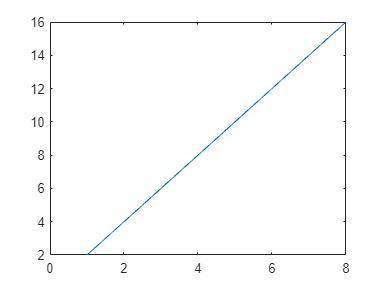

plot(x31, y31)

34. Create a vector of 100 points from 0 to `π `called *x*.

x34 = linspace(0, pi, 100)

x34 =          0    0.0317    0.0635    0.0952    0.1269    0.1587    0.1904    0.2221    0.2539    0.2856    0.3173    0.3491    0.3808    0.4125    0.4443    0.4760    0.5077    0.5395    0.5712    0.6029    0.6347    0.6664    0.6981    0.7299    0.7616    0.7933    0.8251    0.8568    0.8885    0.9203    0.9520    0.9837    1.0155    1.0472    1.0789    1.1107    1.1424    1.1741    1.2059    1.2376    1.2693    1.3011    1.3328    1.3645    1.3963    1.4280    1.4597    1.4915    1.5232    1.5549


y34 = sin(x34)

y34 =          0    0.0317    0.0634    0.0951    0.1266    0.1580    0.1893    0.2203    0.2511    0.2817    0.3120    0.3420    0.3717    0.4009    0.4298    0.4582    0.4862    0.5137    0.5406    0.5671    0.5929    0.6182    0.6428    0.6668    0.6901    0.7127    0.7346    0.7557    0.7761    0.7958    0.8146    0.8326    0.8497    0.8660    0.8815    0.8960    0.9096    0.9224    0.9341    0.9450    0.9549    0.9638    0.9718    0.9788    0.9848    0.9898    0.9938    0.9969    0.9989    0.9999


35.  Plot `y`` = sin(``x``)`.

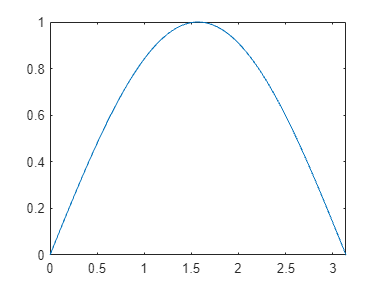

plot(x34, y34)

36.  Find out in the documentation how to change the line color and style (change as you see fit).

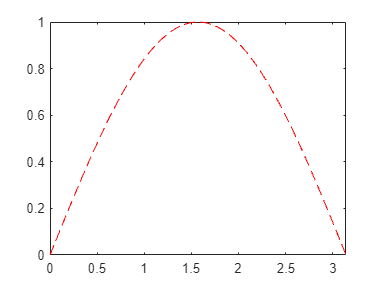

plot(x34, y34, '--r')